# Figure S2I

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'A056_data.mat'],'S','settings','allIF');
conditions = settings.conditions

conditions = 20×5 cell array
    {'siDBF4 DOX'          }    {[2 3 4]}    {[2]}    {[1]}    {[1]}
    {'siDBF4 DMSO'         }    {[5 6 7]}    {[2]}    {[1]}    {[1]}
    {'siCDC7 DOX'          }    {[2 3 4]}    {[3]}    {[1]}    {[1]}
    {'siCDC7 DMSO'         }    {[5 6 7]}    {[3]}    {[1]}    {[1]}
    {'siDonson DOX'        }    {[2 3 4]}    {[4]}    {[1]}    {[1]}
    {'siDonson DMSO'       }    {[5 6 7]}    {[4]}    {[1]}    {[1]}
    {'siCdh1 DOX'          }    {[2 3 4]}    {[5]}    {[1]}    {[1]}
    {'siCdh1 DMSO'         }    {[5 6 7]}    {[5]}    {[1]}    {[1]}
    {'siRif1 DOX'          }    {[2 3 4]}    {[6]}    {[1]}    {[1]}
    {'siRif1 20 DMSO'      }    {[5 6 7]}    {[6]}    {[1]}    {[1]}
    {'siCdc20 DOX'         }    {[2 3 4]}    {[7]}    {[1]}    {[1]}
    {'siCdc20 DMSO'        }    {[5 6 7]}    {[7]}    {[1]}    {[1]}
    {'siEmi1 DOX'          }    {[2 3 4]}    {[8]}    {[1]}    {[1]}
    {'siEmi1 DMSO'         }    {[5 6 7]}    {[8]}    {[1]}    {[1]}
    {

framesPerHr = 60/12;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

ALL_row = [2:7];



for i = 1:length(S)
     S(i).frameDrugAdded = settings.conditions{i,5};
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = (S(i).frameDrugAdded - S(i).POI)/framesPerHr;
end

**Gate cells**

xthresh = 2e6; %x value of peak
xrange = linspace(4.5e6,1000); %row vector of 1000 points between x and y (all the data)
for i = 1:length(allIF)
    xdata = allIF(i).DNA;
    [f, xi] = ksdensity(xdata,xrange); %probility density plot of values from all xdata to xrange - max x of first peak
    xi_trunc = xi(xi<xthresh); %xi_trunc = all xdata <x thresh (peak of first peak)
    f_trunc = f(xi<xthresh); % f_trunc = probability density estimate for all xdata <x tresh
    [~, maxi] = max(f_trunc); %maxi = index of peak
    N_peak = xi_trunc(maxi); %peak is max of (all xdata<x thresh) which is at index maxi
    S(i).DNA_peak = N_peak;
end


**Normalized**

ans = 21860

ans = 18547

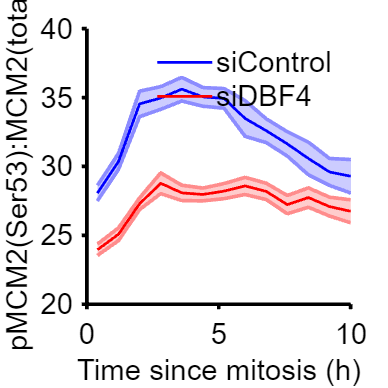

conds=[20 2] ;
poi_list = [1];
offset=0;

colors = [0 0 1;1 0 0;.941 .447 .282;.333 .302 .541; 1 .831 0; 1 .647 .671; .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];
gateVals = {{},{},{},{},{},{},{},{}};
rangeVals = {{[]},{[]},{[]},{[]},{[]},{[]},{[]},{[]}};
name = {'mitosis','APC inact','S phase start'};
edges = (0:(4/framesPerHr):24);
lims = {[0 10],[0 10],[0 10]};
for p = 1:length(poi_list)
    poiAligned=poi_list(p);
   
    f1 = figure('unit','inches','position',[0 0 4 4]);
    for i=1:length(conds)
        
        ind= ~isnan(S(conds(i)).POI_time(:,poiAligned));
        xdata = S(conds(i)).POI_time(ind,poiAligned);
        ydata = [];
        ydata(:, 1) = (S(conds(i)).iRFP1(ind)-1000);
        ydata(:, 2) = log2(S(conds(i)).dna(ind));
        ydata(:, 3) = (S(conds(i)).YFP1(ind));
        ydata(:,4) = ydata(:,1)./ydata(:,3);
sum (ind)
   

        [binData, edges] = bin_xy(xdata, ydata, {'mean','median','std'},...
            'Edges',edges);
        midpoints = edges + (edges(2) -edges(1))/2;
        midpoints = midpoints(1:end-1);

                    bin_gate = binData(4).numCells > 10;

        figure(f1)
    
       hold on
     

           shadedErrorBar(midpoints(bin_gate), binData(4).mean(bin_gate), 2*binData(4).std(bin_gate)./sqrt(binData(4).numCells(bin_gate)),'lineProps',{'Color',colors(i,:),'LineWidth',1.5})
        xlabel(['Time since ' name{p} ' (h)']);
        ylabel('pMCM2(Ser53):MCM2(total)');
        xlim(lims{p});
    

      ylim([20 40]);

    end
    figure(f1)
    hold on
    legend('siControl','siDBF4','fontsize',16,'box','off')
    set(gca,'fontsize',16,'linewidth',2)

end

% print_pdf(['fig_S2I.pdf'])

